# Quantum Mechanics of Noninteracting Electrons in 1D Box 

## Schrödinger Equation

Schrödinger equation describing evolution of a single particle wave function $\Psi(x, t)$ in one-dimensional (1D) space is:


$$\begin{array}{cc}i \hbar \frac{\partial \Psi}{\partial t}=\hat H(x,t) \Psi(x,t),& \qquad (1)\\ \end{array}$$


where $\hbar$ is the reduced Planck's constant, $\hat H=-\frac{\hbar^{2}}{2 m} \frac{d^{2}}{d x^{2}}+V$ is the Hamilton operator (Hamiltonian) of the system, $m$ is the mass of the particle, and $V$ is external potential $V=V(x, t)$ that is in general function of space and time. Since $|\Psi(x, t)|^{2}$ is the probability density for finding the particle in the vicinity of point $x$ at time $t$, $\Psi(x, t)$ has to satisfy the normalization condition $\left.\int |\Psi(x, t)\right|^{2} d x=1$ for any $t$.

If $V=V(x)$ , i.e. $V$ is time-independent, the Schrödinger equation can be solved by **separation of variables:** Assuming $\Psi(x, t)=\psi(x) \varphi(t)$ and plugging this ansatz in Eq. (1), then we get for $\varphi(t)$,


$$\begin{array}{cc}\frac{d \varphi}{d t}=-\frac{i E}{\hbar} \varphi,& \qquad (2)\\ \end{array}$$


where $E$ is the energy, solution of the following **time-independent Schrödinger equation**:


$$\begin{array}{cc}-\frac{\hbar^{2}}{2 m} \frac{d^{2} \psi}{d x^{2}}+V \psi=E \psi.& \qquad (3)\\ \end{array}$$
 

From Eq. (2) $\varphi$ can be solved as

syms varphi(t) E h
ode = diff(varphi,t) == -1i*E/h*varphi

$$ode(t) = \frac{\partial }{\partial t}\phi \left(t\right)=-\frac{\text{E}\,\phi \left(t\right)\,\mathrm{i}}{h}$$

dsolve(ode)

$$ans = C_{1}\,{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}}{h}}$$

We will take $\varphi(t)=e^{-i E t / \hbar}$ and absorb constant $C_1$ into the normalization of $\psi$. Solutions of Eq.(3), $\psi$ and E are eigen vector and eigen value pair of the time-independent Hamiltonian. 

## Quantum Particle in a Box, Quantization of Energy Levels

Suppose the particle is restricted to move freely inside a box with length $L$ , i.e. 


$$\begin{array}{cccc} V(x)= \begin{cases}0 & 0 \leq x \leq L \\ \infty & \text { otherwise }\end{cases}\\ \end{array}$$
 

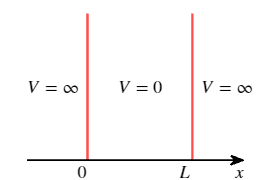

figure;
hold on
L = 1;
xline(0, 'Color', 'r', 'LineStyle', '-','LineWidth',2);
xline(L, 'Color', 'r', 'LineStyle', '-','LineWidth',2);
axis([-L/2 3*L/2 0 L])
box off
axis off
annotation('arrow', [0.1 0.9],[0.11 0.11]);
text(L/2,L/2,'$V=0$','HorizontalAlignment','center','FontSize',15,'Interpreter','latex')
text(-L/3,L/2,'$V=\infty$','HorizontalAlignment','center','FontSize',15,'Interpreter','latex')
text(4*L/3,L/2,'$V=\infty$','HorizontalAlignment','center','FontSize',15,'Interpreter','latex')
text(3*L/2,-0.08,'$x$','HorizontalAlignment','right','FontSize',15,'Interpreter','latex')
text(0,-0.08,'$0$','HorizontalAlignment','right','FontSize',15,'Interpreter','latex')
text(L,-0.08,'$L$','HorizontalAlignment','right','FontSize',15,'Interpreter','latex')
hold off
set(gcf,'Position',[100 100 300 200])

The Schrödinger equation Eq. (3) inside the box becomes


$$\begin{array}{cc}-\frac{\hbar^{2}}{2 m} \frac{d^{2} \psi}{d x^{2}}=E \psi& \qquad (4)\\ \end{array}$$
 

or


$$\begin{array}{cc}\frac{d^{2} \psi}{d x^{2}}=-k^{2} \psi, \text { where } k \equiv \frac{\sqrt{2 m E}}{\hbar}.& \qquad (5)\\ \end{array}$$
 

Here, kinetic energy $E$ can not be negative, hence $k$ is real. Eq. (5) is a simple harmonic oscillator equation with a generic solution 


$$\begin{array}{cc}\psi(x)=C_{1} \sin (k x)+C_{2} \cos (k x)& \qquad (6)\\ \end{array}$$
 

syms psi(x) L k_n
assume(k_n,'real')
assume(L>0)
ode = laplacian(psi,x) == -k_n^2*psi

$$ode(x) = \frac{\partial^{2}}{\partial x^{2}}\psi \left(x\right)=-{k_{n}}^{2}\,\psi \left(x\right)$$

cond = psi(0) == 0;
psi(x) = dsolve(ode,cond)

$$psi(x) = -C_{1}\,\sin\left(k_{n}\,x\right)$$

[k_Allowed,parameters,conditions] = solve(psi(L)==0,k_n,'ReturnConditions',true)

$$k\_Allowed = \frac{\pi \,k}{L}$$

$$parameters = k$$

$$conditions = k\in \mathbb{Z}\wedge C_{1}\neq 0$$

Because the particle can not move outside the box, by the continuity of $\psi(x)$, the boundary conditions are: $\psi(0)=\psi(L)=0$ . Thus, $C_{2}=0$ and $k_{n} L= n\pi$. The distinct solutions of Eq. (5) are parametrized by quantum numbers


$$\begin{array}{cc}k_{n}=\frac{n \pi}{L}, \text { with } n=1,2,3, \ldots \infty& \qquad (7)\\ \end{array}$$


psi(x) = simplify(subs(psi(x),k_n,k_Allowed))

$$psi(x) = -C_{1}\,\sin\left(\frac{\pi \,k\,x}{L}\right)$$

To get the normalized wave functions, we determine $C_1$ as  


$$\begin{array}{cc}\int_{0}^{L}\left|C_{1}\right|^{2} \sin ^{2}(k x) d x=\left|C_{1}\right|^{2} \frac{L}{2}=1, \text { so, } \quad C_{1}=\sqrt{\frac{2}{L}} .& \qquad (8)\\ \end{array}$$
 

syms l 
assume(l,'integer')
C_1=1/simplify(sqrt( int( sin(x*l*pi/L)^2,x,0,L ))) % normalization condition of wave functions

$$C\_1 = \frac{\sqrt{2}}{\sqrt{L}}$$

Finally, orthonormalized set of wave functions are


$$\begin{array}{cc}\psi_{n}(x)=\sqrt{\frac{2}{L}} \sin \left(\frac{n \pi}{L} x\right), \quad n=1,2,3...& \qquad (9)\\ \end{array}$$
 

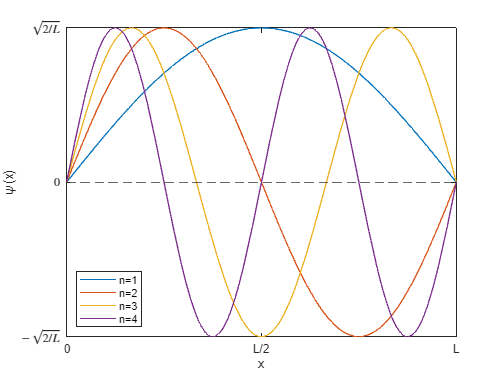

% snippet below plots wave functions for n in [n_min,n_max]
figure;
hold on
n_max=4;
n_min_allowed = string((1:n_max));
n_min = double(n_min_allowed(1));

curve=zeros(1,n_max+1);
curve(1) = yline(0,'LineStyle','--');

syms x;
L = 1;
for n = n_min:n_max
    curve(n+2-n_min)=fplot(sqrt(2/L)*sin(n*pi*x/L),[0,L],'DisplayName',['n=',num2str(n)]);
end
xticks([0,L/2,L])
xticklabels({'0','L/2', 'L'})
yticks([-sqrt(2/L),0,sqrt(2/L)])
yticklabels({'$-\sqrt{2/L}$', '0', '$\sqrt{2/L}$'})
yaxisproperties= get(gca, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'Latex';   
ylim([-sqrt(2/L) sqrt(2/L)])
xlabel('x')
ylabel('\psi(x)')
legend(curve(2:end-n_min+1),'Location','southwest')
box on
hold off

## Orthonormality and Completeness of Wave Functions

Let's now show that these states $\psi_n(x)$ are indeed orthonormal to each other for $n\ge 1$.

syms L x n m positive
assumeAlso(n,'integer')
assumeAlso(m,'integer')
combine(2/L*int(sin(pi*n*x/L)*sin(pi*m*x/L),x,0,L))

$$ans = \left\{ \begin{array}{cl} 1 & \text{ if }m=n\\ 0 & \text{ if }m\neq n \end{array}\right.$$

Next, we prove the completeness of $\frac{\sqrt{2}}{\sqrt{L}}\sin\big(\frac{\pi n x}{L}\big)$ basis for $n=1,2,3,...\infty$. To prove that **any** **physical** **state** $\psi(x,t)$ (satisfying vanishing boundary conditions for $x=0$ and $x=L$) can be expanded in the basis of $\sin(\pi n x/L)$ functions for $x \in [0,L]$, we can define an auxiliary function $f(x,t)$ such that $f(x,t)=\psi(x,t)$ for $x \in [0,L]$, and in $x\in [-L,0)$ region $f(x,t)=-f(-x,t)$. 

After this, we can invoke basic rule from Fourier analysis: any continuous **odd** function defined on $[-L,L]$, and vanishing at $x=L$, can be expanded in the series of sinus functions:


$$f(x,t)=\sum_{n=1}^{\infty} f_n(t) \sin(\pi n x/ L),$$
 

where $f_n(t)=\frac{2}{L}\displaystyle \int_0^L f(x,t) \sin\left( \frac{\pi n x}{L} \right) \mathrm{d} x=\frac{2}{L}\int_0^L \psi(x,t) \sin\left( \frac{\pi n x}{L} \right)\mathrm{d} x$.

Since inside the box region $\psi(x,t)=f(x,t)$, the same expansion 


$$\psi(x,t)=\displaystyle \sum_{n=1}^{\infty} f_n(t) \sin\big(\frac{\pi n x}{L}\big) \qquad (10)$$
 

applies to any physical (finite energy) state $\psi(x,t)$ for $x\in [0,L]$. 

## Energy Levels

The energies corresponding to states Eq. (9) are


$$\begin{array}{cc}E_{n}=\frac{\hbar^{2} k_{n}^{2}}{2 m}=\frac{n^{2} \pi^{2} \hbar^{2}}{2 m L^{2}}.& \qquad (11)\\ \end{array}$$


For the lowest energy, which is also known as the **ground state energy**, we get


$$\begin{array}{cc}E_{1}=\frac{\pi^{2} \hbar^{2}}{2 m L^{2}}.& \qquad (12)\\ \end{array}$$


All excited energy levels are expressed as $E_{n}=n^{2} E_{1}$ for $n=2,3,...\infty$. Particle in the box can not have energy less than the ground state energy. Eigen states of particle in the box have discrete spectrum, given in Eq. (11). If particle inside a box has (average) energy other than given in Eq. (11), particle is in a superposition state of different eigen states. 

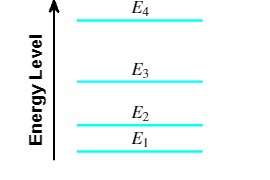

m = 1;
L = 1;
h = 1;
E1 = pi^2*h^2/(2*m*L^2);
n_max = 4;
figure;
hold on;
yticks_list = zeros(n_max,1);
yticks_label_list = cell(n_max,1);
for n = 1:n_max
    En = E1*n^2;
    line([0.2 0.8],[En En],'LineWidth',2,'Color','c')    
    yticks_list(n) = En;
    yticks_label_list{n} = "$E_"+num2str(n)+"$";
    text(0.5,En,"$E_"+num2str(n)+"$",'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',15,'Interpreter','latex','FontWeight','bold')
end
axis([0 1 0 1.05*En]);
axis off
annotation('arrow', [0.2 0.2],[0.11 1]);
text(0.05,En/2,"Energy Level",'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',15,'Rotation',90,'FontWeight','bold')
hold off
set(gcf,'Position',[100 100 300 200])

We can generalize results to D dimensional cube with sides $L_{j}, j=1,2, \ldots D$ as


$$\begin{array}{cc}\psi_{\mathbf{n}}(\mathbf{x})=\prod_{j=1}^{D} \sqrt{\frac{2}{L_{j}}} \sin \left(\frac{\pi n_{j} x_{j}}{L_{j}}\right),& \qquad (13)\\ \end{array}$$


where $\mathbf{x}=\left(x_{1}, x_{2}, \ldots x_{j}, \ldots x_{D}\right)$ and $\mathbf{n}=\left(n_{1}, n_{2}, . . n_{j}, \ldots n_{D}\right).$

For numerical simulation of various quantum mechanical problems, including time-dependent scattering problems in 1D and 2D, see Refs. [1] and [2].

## Ground State Particle Density of N Noninteracting Spinless Electrons in 1D Box

Now let us suppose that there are $N$ noninteracting (spinless) electrons in the 1D box in the ground state. Due to Pauli principle, all the lowest energy states from $n=1$ to $n=N$ are occupied by a single electron in the ground state.

Ground state electron density is $\rho_0(x)= \displaystyle{\sum_{n=1}^N }|\psi_n(x)|^2$ and due to normalization of wave functions in Eq. (9) we have $\displaystyle\int_0^L \rho_0(x)dx =N$.   

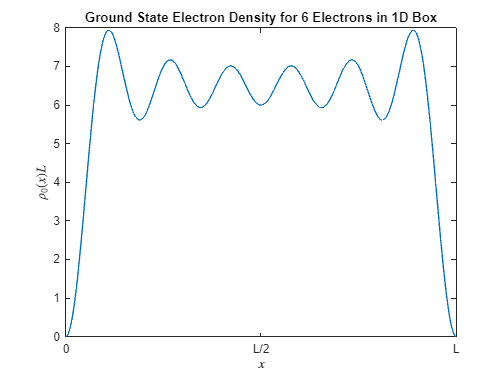

figure;
N=6; % select number of electrons
L = 1;
syms x;
rho=2/L*sin(pi*x/L).^2;

for l=2:N
    rho=rho+2/L*sin(l*pi*x/L).^2;
end
fplot(rho,[0,L]);
xlim([0,L])
xticks([0,L/2,L])
xticklabels({'0','L/2', 'L'})
xlabel('$x$',interpreter='Latex')
ylabel('$\rho_0(x)L$', interpreter='Latex')
title("Ground State Electron Density for "+num2str(N) +" Electrons in 1D Box")

int(rho,[0,L])  % check normalization of density

$$ans = 6$$

Observe $N$ bumps in the density profile. Even though we assumed that electrons do not interact with each other, they prefer to stay apart from each other, due to the Pauli exclusion principle (repulsion due to Fermi statistics). 

## References

1. [Teaching Quantum Mechanics with MATLAB](https://serc.carleton.edu/matlab_computation2016/essays/160271.html)

2. [Double-Slit Experiment in MATLAB](https://www.mathworks.com/matlabcentral/fileexchange/122897-double-slit-and-scattering-two-quantum-particles?s_tid=srchtitle)  